# MATLAB超基本(3)

tableデータの扱い方の例

「フィッシャーのアヤメ」のデータを読み込む．

(table形式でなくても良いのであれば，

で種とそれぞれの長さを別々に読み込める)

tbl_iris=readtable('../data/FisherIris/FisherIris.xlsx', ...
    'VariableNamingRule','preserve');

文字列データを，比較などを行いやすいcategorical型に変換する．

tbl_iris.("種")=categorical(tbl_iris.("種"));

種類として含まれる名前を取り出す

speciesVals=unique(tbl_iris.("種"));

種類ごとにマーカの種類を指定して散布図とする．

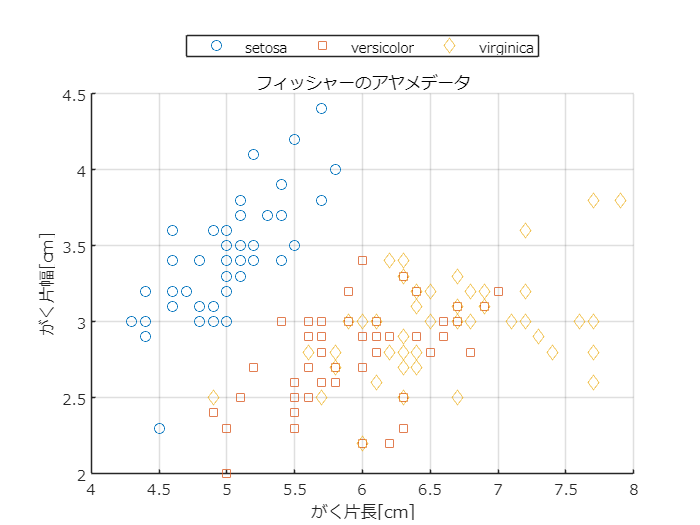

figure;hold on;grid on;
set(gca,'fontname','メイリオ')
for speciesVal=speciesVals'
    % 条件にあった行のみを検索して利用する方法
    ind = tbl_iris.("種")==speciesVal;

    markerType='';
    % 種の名前でマーカの種類を変える
    switch speciesVal
        case speciesVals(1)
            markerType='o';
        case speciesVals(2)
            markerType='s';
        case speciesVals(3)
            markerType='d';
    end

    % マーカの形を指定して散布図を描く
    scatter(tbl_iris.("がく片長")(ind), ...
        tbl_iris.("がく片幅")(ind),markerType);
end

% 長い行は ... で改行するとつながった1行とみなされる．
legend(speciesVals,'location','northoutside', ...
    'orientation','horizontal');
xlabel('がく片長[cm]');
ylabel('がく片幅[cm]');
title('フィッシャーのアヤメデータ');